# [Example script how to use PIVlab from the commandline

Just run this script to see what it does.

You can also adjust the settings in "s" and "p", specify a mask and a region of interest

clc; clear variables; close all
pivlab_dir = fileparts(which("buildfile.m"));
addpath(pivlab_dir); %add the PIVlab folder to search path

Select a number > 1 if you want to use the parallel computing toolbox to perform parallel computing:

nr_of_cores = 1; % integer, 1 means single core, greater than 1 means parallel

## Image files location:

image_root_dir = fullfile(pivlab_dir,'..','data_from_william','stereo_2'); %directory containing the images you want to analyze
image_dir = fullfile(image_root_dir, "PIV images1");
image_ext = 'tif'; % bmp / tif / jpg / tiff / jpeg
pairwise = true; % false for [A+B], [B+C], [C+D]... sequencing style, and true for [A+B], [C+D], [E+F]... sequencing style

## Calibration image settings and files

pattern_type = "charuco-board";
pattern_dims = [7 10];
pattern_name = "DICT_5X5_100";
checker_size = 8.8;  % 100 pixels / 300 pixels-per-inch * 26.4 mm-per-inch)
marker_size = 0.75 * checker_size;

calibration_dir = fullfile(image_root_dir,"moving board");
n_calibration_files = 5;

s = rng(0, "twister");  % Fix RNG seed for reproducibilty

## Standard PIV Settings

settings = cell(15,2); % To make it more readable, let's create a "settings table"
%Parameter                          %Setting			%Options
settings{1,1}= 'Int. area 1';              settings{1,2}=64;			% window size of first pass
settings{2,1}= 'Step size 1';              settings{2,2}=32;			% step of first pass
settings{3,1}= 'Subpix. finder';           settings{3,2}=1;			% 1 = 3point Gauss, 2 = 2D Gauss
settings{4,1}= 'Mask';                     settings{4,2}=[];			% If needed, supply a binary image mask with the same size as the PIV images
settings{5,1}= 'ROI';                      settings{5,2}=[];			% Region of interest: [x,y,width,height] in pixels, may be left empty to process the whole image
settings{6,1}= 'Nr. of passes';            settings{6,2}=2;			% 1-4 nr. of passes
settings{7,1}= 'Int. area 2';              settings{7,2}=32;			% second pass window size
settings{8,1}= 'Int. area 3';              settings{8,2}=16;			% third pass window size
settings{9,1}= 'Int. area 4';              settings{9,2}=16;			% fourth pass window size
settings{10,1}='Window deformation';       settings{10,2}='*linear';	% '*spline' is more accurate, but slower
settings{11,1}='Repeated Correlation';     settings{11,2}=0;			% 0 or 1 : Repeat the correlation four times and multiply the correlation matrices.
settings{12,1}='Disable Autocorrelation';  settings{12,2}=0;			% 0 or 1 : Disable Autocorrelation in the first pass.
settings{13,1}='Correlation style';        settings{13,2}=0;			% 0 or 1 : Use circular correlation (0) or linear correlation (1).
settings{14,1}='Repeat last pass';			settings{14,2}=0;			% 0 or 1 : Repeat the last pass of a multipass analyis
settings{15,1}='Last pass quality slope';  settings{15,2}=0.025;		% Repetitions of last pass will stop when the average difference to the previous pass is less than this number.

## Standard image preprocessing settings

preprocessing = cell(10,1);
%Parameter                       %Setting           %Options
preprocessing{1,1}= 'ROI';                   preprocessing{1,2}=settings{5,2};     % same as in PIV settings
preprocessing{2,1}= 'CLAHE';                 preprocessing{2,2}=1;          % 1 = enable CLAHE (contrast enhancement), 0 = disable
preprocessing{3,1}= 'CLAHE size';            preprocessing{3,2}=50;         % CLAHE window size
preprocessing{4,1}= 'Highpass';              preprocessing{4,2}=0;          % 1 = enable highpass, 0 = disable
preprocessing{5,1}= 'Highpass size';         preprocessing{5,2}=15;         % highpass size
preprocessing{6,1}= 'Clipping';              preprocessing{6,2}=0;          % 1 = enable clipping, 0 = disable
preprocessing{7,1}= 'Wiener';                preprocessing{7,2}=0;          % 1 = enable Wiener2 adaptive denoise filter, 0 = disable
preprocessing{8,1}= 'Wiener size';           preprocessing{8,2}=3;          % Wiener2 window size
preprocessing{9,1}= 'Minimum intensity';     preprocessing{9,2}=0.0;        % Minimum intensity of input image (0 = no change)
preprocessing{10,1}='Maximum intensity';     preprocessing{10,2}=1.0;       % Maximum intensity on input image (1 = no change)


## Postprocessing settings

postprocessing = cell(6,1);
%Parameter     %Setting                                     %Options
postprocessing{1,1}= 'Calibration factor, 1 for uncalibrated data';      postprocessing{1,2}=1;                   % Calibration factor for u
postprocessing{2,1}= 'Calibration factor, 1 for uncalibrated data';      postprocessing{2,2}=1;                   % Calibration factor for v
postprocessing{3,1}= 'Valid velocities [u_min; u_max; v_min; v_max]';    postprocessing{3,2}=[-50; 50; -50; 50];  % Maximum allowed velocities, for uncalibrated data: maximum displacement in pixels
postprocessing{4,1}= 'Stdev check?';                                     postprocessing{4,2}=1;                   % 1 = enable global standard deviation test
postprocessing{5,1}= 'Stdev threshold';                                  postprocessing{5,2}=7;                   % Threshold for the stdev test
postprocessing{6,1}= 'Local median check?';                              postprocessing{6,2}=1;                   % 1 = enable local median test
postprocessing{7,1}= 'Local median threshold';                           postprocessing{7,2}=3;                   % Threshold for the local median test


## Calibrate cameras

cam1_files = dir(fullfile(calibration_dir, ['CAM1*A.', image_ext]));
cam2_files = dir(fullfile(calibration_dir, ['CAM2*A.', image_ext]));
image_indices = [5,7,14,15,19,25,30,40,51,64];
cam1_files = cam1_files(image_indices);
cam2_files = cam2_files(image_indices);
cam1_files = strcat({cam1_files.folder}', filesep, {cam1_files.name}');
cam2_files = strcat({cam2_files.folder}', filesep, {cam2_files.name}');
image_size = size(imread(cam1_files{1}));

worldPoints = patternWorldPoints(pattern_type, pattern_dims, checker_size);
stereo_image_points = detectCharucoBoardPoints(cam1_files, cam2_files, pattern_dims, pattern_name, checker_size, marker_size);
% stereo_parameters = estimateCameraParameters(stereo_image_points, worldPoints, ImageSize=image_size);
% Estimate camera intrinsics: camera calibrator, fill the image with
camera_1_parameters = estimateCameraParameters(stereo_image_points(:,:,:,1), worldPoints, ImageSize=image_size);
camera_2_parameters = estimateCameraParameters(stereo_image_points(:,:,:,2), worldPoints, ImageSize=image_size);
stereo_parameters = estimateStereoBaseline(stereo_image_points, worldPoints, camera_1_parameters, camera_2_parameters);
% calibration grid
% estimateStereoBaseline

## Get transforms to laser light plane

A set of features taken from the images of the laser light plane are detected and matched between the cameras. Multiple corresponding images from the two cameras can be used. 

A set of matched points between images of the laser light planeo obtain a projection transform to warp the image such that the image plane is parallel to the laser light plane

CAM1_PIVlab_0000_A.tif
CAM1_PIVlab_0003_A.tif
CAM1_PIVlab_0006_A.tif
CAM1_PIVlab_0009_A.tif
CAM1_PIVlab_0012_A.tif
CAM1_PIVlab_0015_A.tif
CAM1_PIVlab_0018_A.tif
CAM1_PIVlab_0021_A.tif
CAM1_PIVlab_0024_A.tif
CAM1_PIVlab_0027_A.tif
CAM1_PIVlab_0030_A.tif
CAM1_PIVlab_0033_A.tif
CAM1_PIVlab_0036_A.tif
CAM1_PIVlab_0039_A.tif
CAM1_PIVlab_0042_A.tif
CAM1_PIVlab_0045_A.tif
CAM1_PIVlab_0048_A.tif


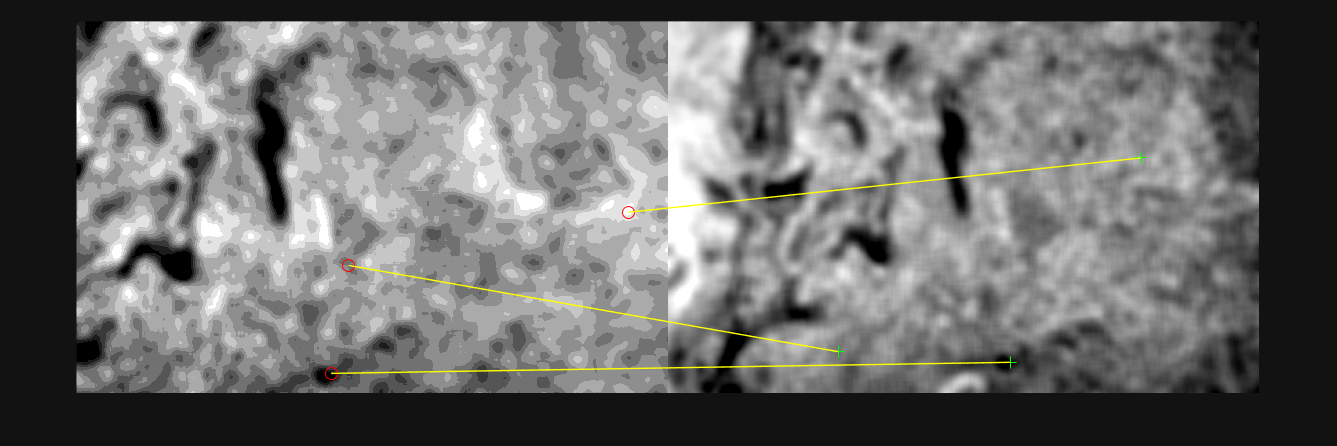

cam1_files = dir(fullfile(image_dir, filesep, ['CAM1*.', image_ext]));
cam2_files = dir(fullfile(image_dir, filesep, ['CAM2*.', image_ext]));
matchedPoints1 = {};
matchedPoints2 = {};
for indx = 1:6:length(cam1_files)
    % Load images and extract features
    img = imread(image_dir + filesep + cam1_files(indx).name);
    [img1, f1, points_obj1] = stereopivfunctions.image_feature_extraction(img);

    img = imread(image_dir + filesep + cam2_files(indx).name);
    [img2, f2, points_obj2] = stereopivfunctions.image_feature_extraction(img);
    
    % Match features between the the two cameras
    indexPairs = matchFeatures(f1, f2, MatchThreshold=2, Unique=true); % MaxRatio=0.5);
    % Optional plotting
    if size(indexPairs,1) > 0
        disp(cam1_files(indx).name)
        i1 = img1; i2 = img2;
        showMatchedFeatures(i1, i2, points_obj1(indexPairs(:,1)), points_obj2(indexPairs(:,2)), 'montage');
    end
    % Store matched points
    matchedPoints1{end+1} = points_obj1(indexPairs(:,1));
    matchedPoints2{end+1} = points_obj2(indexPairs(:,2));
end

The estimateFundamentalMatrix function is used to find a set of inlier points (points with a high degree of certainty about the quality of the match), which can be used to calculate the normal of the laser light plane and the transformation required to convert the 3-D coordinates of the matched points to coordinates in the 2-D plane of the laser light field

% Reduce matched points to a set of inliers
mp1 = vertcat(matchedPoints1{:});
mp2 = vertcat(matchedPoints2{:});
[~,is_inlier,~] = estimateFundamentalMatrix( ...
    mp1.Location, ...
    mp2.Location, ...
    method="MSAC", ...
    Confidence=65, ...
    DistanceThreshold=10 ...
);

mp1 = mp1(is_inlier);
mp2 = mp2(is_inlier);
disp(find(is_inlier))

    17
    20
    22
    23
    24
    25
    28
    30
    31
    32
    37
    39
    41
    42
    43
    47
    50
    51
    52
    53
    61
    63
    65
    69
    71
    74
    76
    77
    78
    81
    92
    94
    96
    97
   101
   104
   112
   120
   121
   122
   128
   134
   136
   139
   149
   150



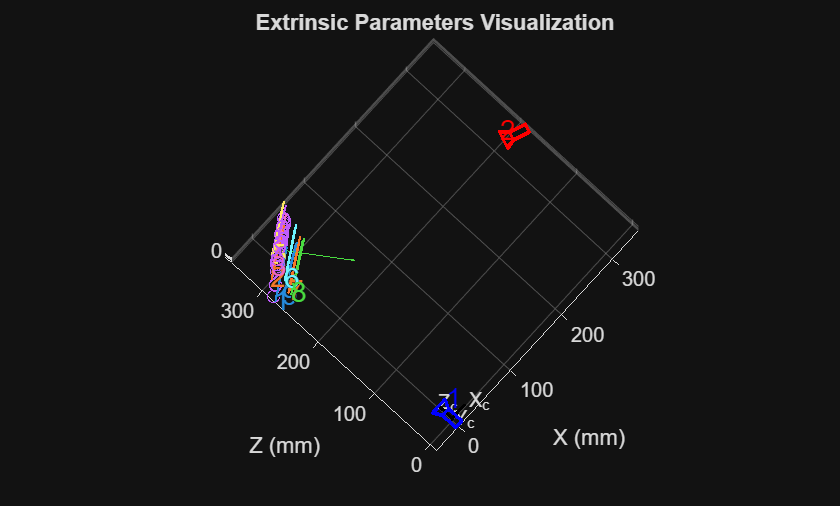


% Triangulate the position of the points and then compute the normal to the
% laser light plane and the 2-D coordinates of the matched points in the
% laser light plane
points = triangulate(mp1.Location, mp2.Location, stereo_parameters);
[coords, normal, mu, tform3d] = stereopivfunctions.two_d_coords_of_points(points);

% Plot the results for inspection
figure
hold on
showExtrinsics(stereo_parameters)
scatter3(points(:,1), points(:,3), points(:,2))
quiver3(mu(1), mu(3), mu(2), normal(1), normal(3), normal(2), 100)
hold off

view([-47.5 85.5])

Given the position of the matched points in the images and the 2-D coordinates of the same points in the laser ight field, a projective transformation is computed to transform the images such that the iamges are as if the camera is perpendicular to the laser light field.

% Get the projection transform
tform1 = fitgeotform2d(mp1.Location, coords, "projective");
tform2 = fitgeotform2d(mp2.Location, coords, "projective");

## Create list of images inside user specified directory

files = dir(fullfile(image_dir, ['*.', image_ext]));
filenames = string({files.name})';
filenames = sortrows(filenames); %sort all image files

## Pre-load the image names out side of the parallelizable loop

n_cameras = 2;
filenames = reshape(filenames, [], n_cameras);
cam1_filenames = reshape(filenames(:,1)', 2, [])';
cam2_filenames = reshape(filenames(:,2)', 2, [])';
slicedfilename1A = cellstr(cam1_filenames(:,1));
slicedfilename1B = cellstr(cam1_filenames(:,2));
slicedfilename2A = cellstr(cam2_filenames(:,1));
slicedfilename2B = cellstr(cam2_filenames(:,2));

Draw a pair of original images, the transformed representations, and the masked data where all parts of the combined image for which data comes from there only one (or no) cameras.

ii = 3

ii = 3

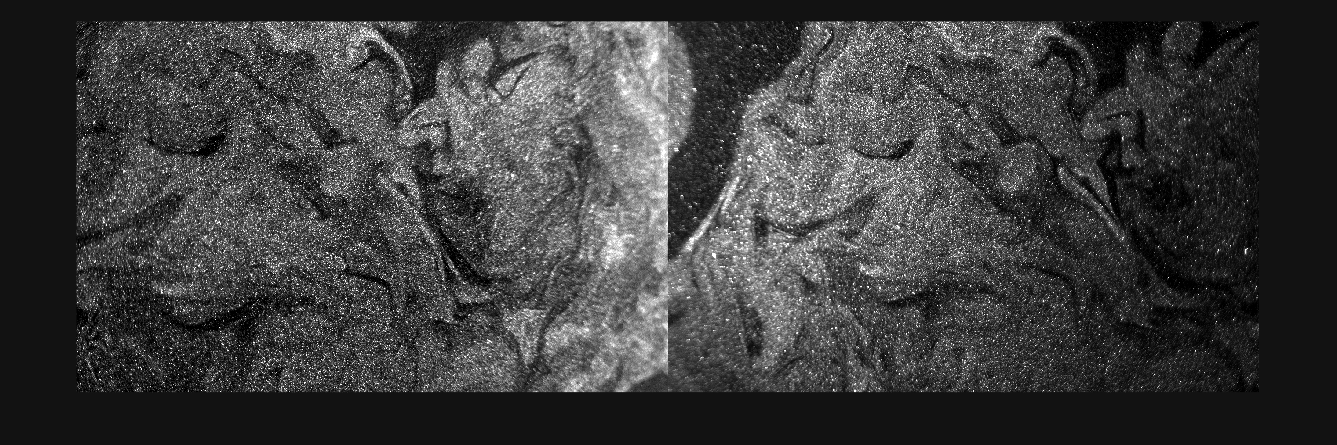


img1 = imread(fullfile(image_dir, slicedfilename1A{ii}));
img2 = imread(fullfile(image_dir, slicedfilename2A{ii}));
imshowpair(imadjust(img1), imadjust(img2),"montage")

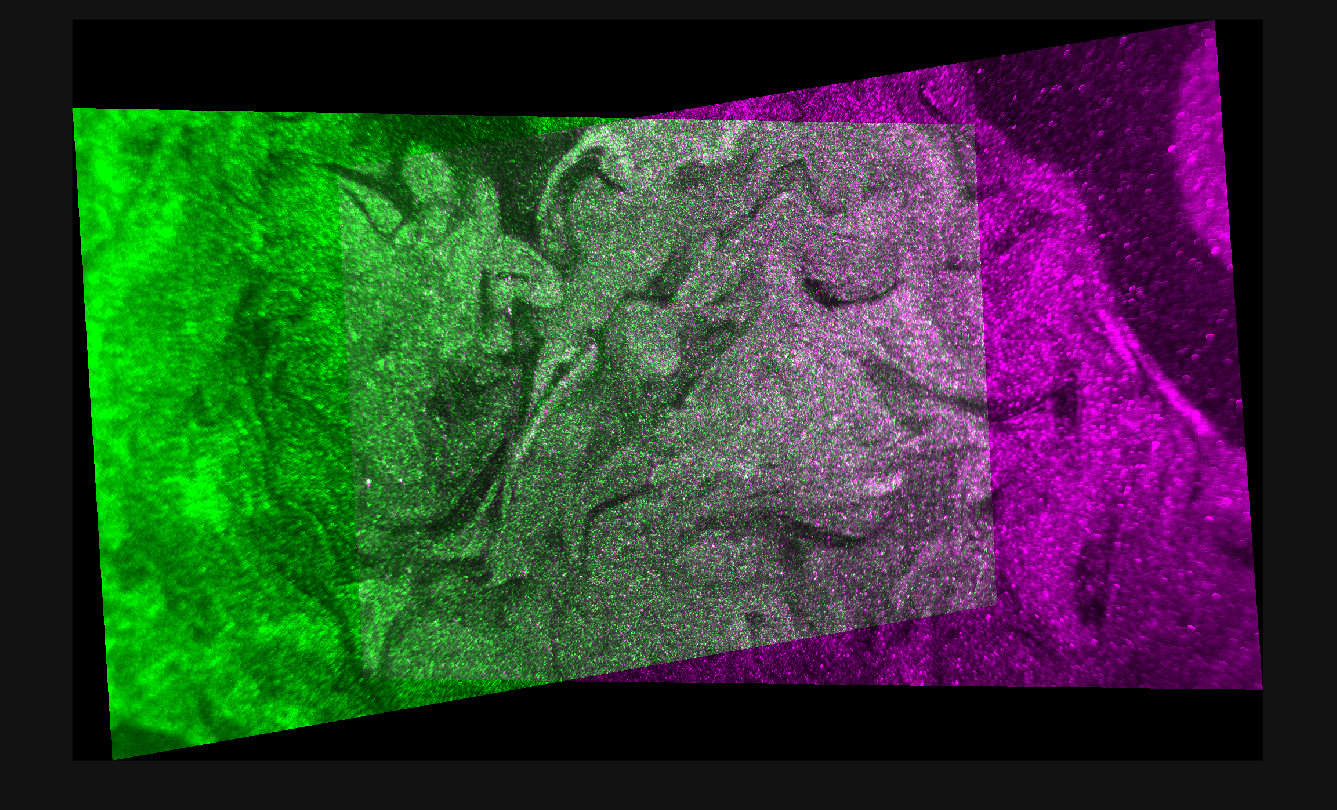


[output_view] = stereopivfunctions.compute_output_view(image_size, tform1, tform2);

[img1w] = imwarp(img1, tform1, 'cubic', OutputView=output_view);
[img2w] = imwarp(img2, tform2, 'cubic', OutputView=output_view);

imshowpair(imadjust(img1w), imadjust(img2w))

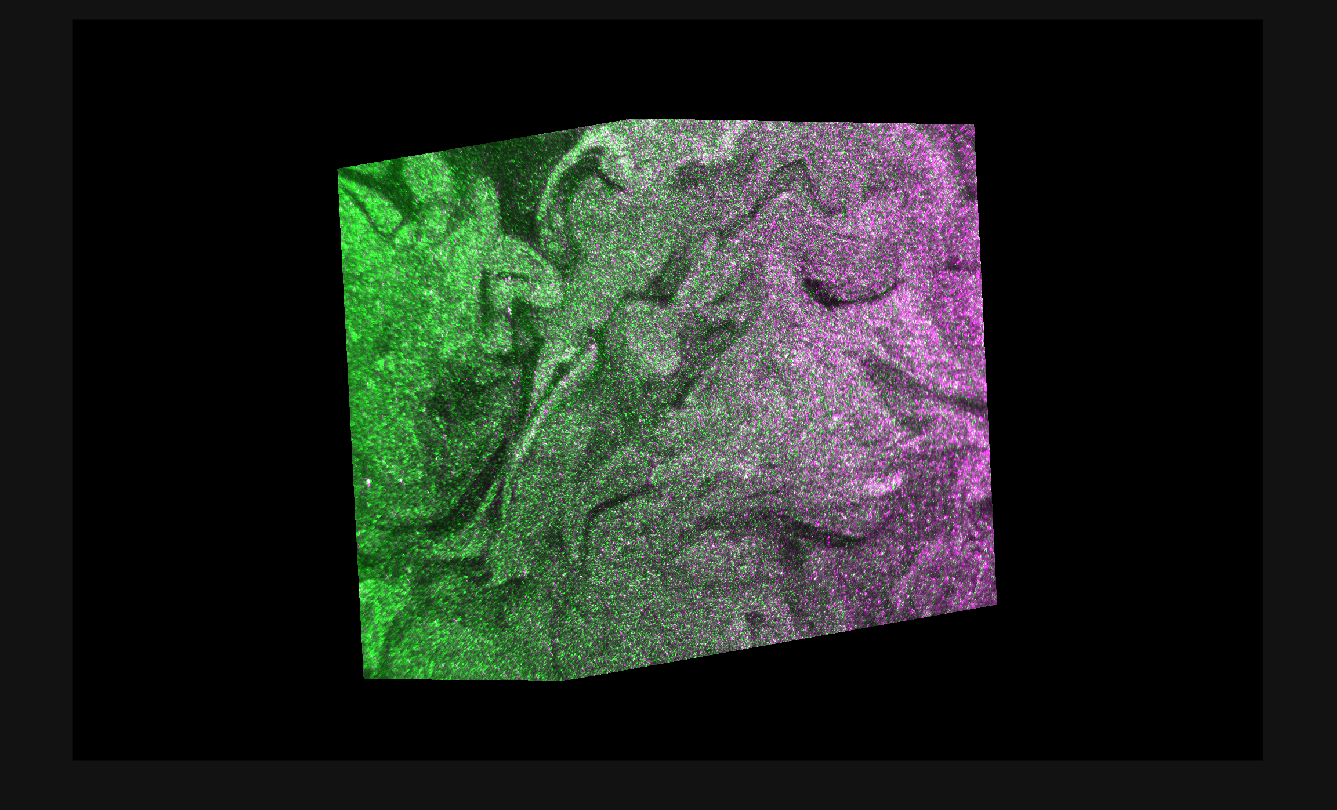


[img1c, img2c, mask] = stereopivfunctions.image_intersection(img1w, img2w);

settings{4,1}= 'Mask';                     settings{4,2}=mask;			% If needed, supply a binary image mask with the same size as the PIV images
settings{5,1}= 'ROI';                      settings{5,2}=[];

imshowpair(imadjust(img1c), imadjust(img2c))

## Main PIV analysis

Run correlation is just a functionalised version of what was in the original "Example_PIVlab_commandline" script, but know with extra arguments needed by the piv_analysis function to transform the images.

[x1, y1, u1, v1, typevector1, correlation_map1] = stereopivfunctions.run_correlation(...
    image_dir, slicedfilename1A(1:5), slicedfilename1B(1:5), preprocessing, settings, nr_of_cores, tform1, output_view...
);

Processing: 
100 %


[x2, y2, u2, v2, typevector2, correlation_map2] = stereopivfunctions.run_correlation(...
    image_dir, slicedfilename2A(1:5), slicedfilename2B(1:5), preprocessing, settings, nr_of_cores, tform2, output_view ...
);

Processing: 
100 %


The most important results are x,y,u,v. These can now be viewed before validation:

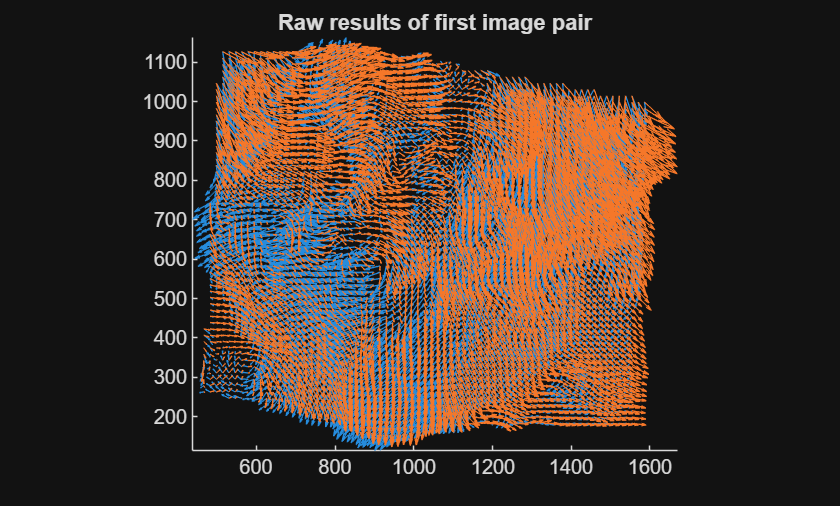

ii = 1;
figure;
hold on
quiver(x1{ii},y1{ii},u1{ii},v1{ii},5);
quiver(x1{ii},y1{ii},u2{ii},v2{ii},5);
hold off
axis image
title('Raw results of first image pair')

## STOP HERE!

### The following does not work as required. The alpha/beta angles required for the 3-D velocity calculation are not yet correctly computed.

The tangent of the alpha and beta angles must be calculated. The angles are the vertical and horizontal angle betwwen the unit normal of the laser light field and the vector connecting the camera and the point in the laser light field where a velocity vector has been calculated. 

The x and y coordinate pairs from the correlation function need to transformed back to the original image coordinates. The stereo camera parameters can then be used to triangulate the positions of the x,y coordinate pairs in 3-D space. Then the vectors connecting the cameras to the points can then be calculated. The vectors defining 'vertical' and 'horizontal' can be caluclated as the vector connecting one coordinate point to its neighbours. The angles can be caluted as the angle betwwen the normal of the laser light plane and the normal of the plane defined by the camera-point vector and the inplane vertical/horizontal vector.

Note the the tangent of the angle is needed and not the angle itself. This canbe obtained using dot and cross products without the need need for any arctangent/sine/cosine operations.

% This box has been used as a scratch pad for figuring out what should be
% in the "stereopivfunctions.get_tan_angles" function.

center1 = tform1.transformPointsForward(camera_1_parameters.Intrinsics.PrincipalPoint);
center2 = tform2.transformPointsForward(camera_2_parameters.Intrinsics.PrincipalPoint);

grid_points = [x1{1}(:) y1{1}(:)];
[a,b] = output_view.intrinsicToWorld(grid_points(:,1), grid_points(:,2));

d1 = mu(3);  % The distance to the laser light field from camera 1 in mm
d2 = sqrt(sum((stereo_parameters.PoseCamera2.invert().Translation - mu) .^ 2));  % The distance to the laser light field from camera 2 in mm
c1 = tform1.transformPointsForward([a,b] - center1) - tform1.A(1:2,3)';
c2 = tform2.transformPointsForward([a,b] - center2) - tform2.A(1:2,3)';

c1 = tform1.transformPointsForward([X(:),Y(:)]);
c2 = tform2.transformPointsForward([X(:),Y(:)]);
ep1 = tform3d.transformPointsForward([c1, zeros(size(X(:)))]);
ep2 = tform3d.transformPointsForward([c2, zeros(size(X(:)))]);


[alpha1, beta1] = stereopivfunctions.get_tan_angles(c1, d1);
[alpha2, beta2] = stereopivfunctions.get_tan_angles(c2, d2);
alpha1 = reshape(alpha1, size(x1{1}));
beta1 = reshape(beta1, size(x1{1}));
alpha2 = reshape(alpha2, size(x1{1}));
beta2 = reshape(beta2, size(x1{1}));

## Calculate the new 3-d velocities using 

u = (u1 * tan(alpha2) + u2 * tan(alpha1)) / (tan(alpha1) + tan(alpha2))

v = (v1 * tan(beta2) + v2 * tan(beta2)) / (tan(beta1) + tan(beta2))

w = (u1 - u2) / (tan(alpha1) + tan(alpha2))

or

w = (v1 + v2) / (tan(beta1) + tan(beta2))

if one of the denominators approaches zero (eg $\tan \left(\beta 1\right)+\tan \left(\beta 2\right)$)  then use

v = 0.5 * (v1+v2) + 0.5 * w * (tan(beta1) - tan(beta2))

to avoid the singularity

## This should work correctly IFF alpha and beta angles are correct!

U = cell(size(u1));
V = U;
W = U;
for indx = 1:length(u1)
    [U{indx}, V{indx}, W{indx}] = stereopivfunctions.recover_3d_velocities( ...
        u1{indx}, v1{indx}, alpha1, beta1, u2{indx}, v2{indx}, alpha2, beta2 ...
    );
end

figure;
hold on
wx = x2{ii};
wy = y2{ii};
wc = W{ii};
scatter(wx(:), wy(:), [], wc(:), "filled")
quiver(x2{ii}, y2{ii}, U{ii}, V{ii}, 5);
hold off
axis image
title('Resolved results of first image pair')

## From here on is standard postprocessing for single camera PIV

disp("A break")

## PIV postprocessing loop

Standard image post processing settings

u_filt=cell(size(u));
v_filt=cell(size(v));
typevector_filt=typevector;

if nr_of_cores >1 % parallel loop

	if misc.pivparpool('size')<nr_of_cores
		misc.pivparpool('open',nr_of_cores);
	end

	parfor PIVresult=1:size(x,1)

		[u_filt{PIVresult,1}, v_filt{PIVresult,1},typevector_filt{PIVresult,1}]= ...
			post_proc_wrapper(u{PIVresult,1},v{PIVresult,1},typevector{PIVresult,1},postprocessing,true);

	end

else % sequential loop

	for PIVresult=1:size(x,1)

		[u_filt{PIVresult,1}, v_filt{PIVresult,1},typevector_filt{PIVresult,1}]= ...
			post_proc_wrapper(u{PIVresult,1},v{PIVresult,1},typevector{PIVresult,1},postprocessing,true);

	end

end

Post-processing finished, here are the filtered results:

figure;quiver(x{1},y{1},u_filt{1},v_filt{1},5);axis image; %(the last number determines the displayed sclae of the vectors)
title('Filtered results of first image pair')

## clean up parallel pool, and cluster (if required, will save RAM)

%{
if nr_of_cores >1 % parallel
	poolobj = gcp('nocreate'); % GET the current parallel pool
	if ~isempty(poolobj ); delete(poolobj );end
	clear local_cluster;
end
%}

Save the data to a Matlab file

save(fullfile(directory, [filenames{1} '_' filenames{end} '_' num2str(amount) '_frames_result_.mat']));

Clean up unused vars

clearvars -except p s r x y u v typevector directory filenames u_filt v_filt typevector_filt correlation_map
disp('DONE.')


Wrapper function for PIVlab_postproc

function [u_filt, v_filt,typevector_filt] = post_proc_wrapper(u,v,typevector,post_proc_setting,paint_nan)
% wrapper function for postproc.PIVlab_postproc

% INPUT
% u, v: u and v components of vector fields
% typevector: type vector
% post_proc_setting: post processing setting
% paint_nan: bool, whether to interpolate missing data

% OUTPUT
% u_filt, v_filt: post-processed u and v components of vector fields
% typevector_filt: post-processed type vector


[u_filt,v_filt] = postproc.PIVlab_postproc(u,v, ...
	post_proc_setting{1,2},...
	post_proc_setting{2,2},...
	post_proc_setting{3,2},...
	post_proc_setting{4,2},...
	post_proc_setting{5,2},...
	post_proc_setting{6,2},...
	post_proc_setting{7,2});

typevector_filt = typevector; % initiate
typevector_filt(isnan(u_filt))=2;
typevector_filt(isnan(v_filt))=2;
typevector_filt(typevector==0)=0; %restores typevector for mask

if paint_nan
	u_filt=misc.inpaint_nans(u_filt,4);
	v_filt=misc.inpaint_nans(v_filt,4);
end


end